# Problem Set 3

## Problem 1

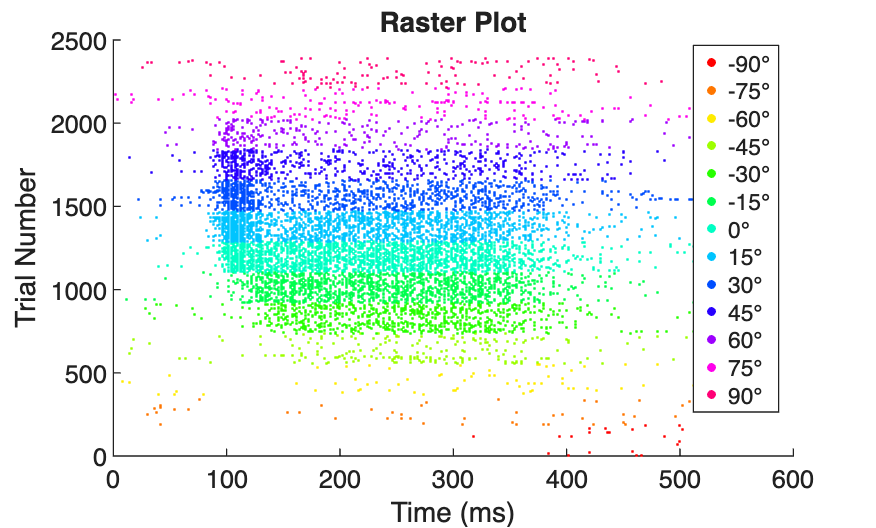

numTimes = size(mtNeuron.data, 1);
numDirections = size(mtNeuron.data, 2);
numTrials = size(mtNeuron.data, 3);

colors = hsv(numDirections);
directions = linspace(-90, 90, numDirections);

figure; hold on;
trial_offset = 0;
legend_handles = gobjects(numDirections,1);

for direction = 1:numDirections
    for trial = 1:numTrials
        % convert to ms
        spikes = find(mtNeuron.data(:, direction, trial)) * 2;
        y = (trial_offset + trial) * ones(size(spikes));

        plot(spikes, y, '.', 'Color', colors(direction, :), 'MarkerSize', 1);
    end
    
    legend_handles(direction) = plot(nan, nan, '.', ...
        'Color', colors(direction, :), 'MarkerSize', 10);
    
    trial_offset = trial_offset + numTrials;
end

xlabel('Time (ms)');
ylabel('Trial Number');
title('Raster Plot');
legend(legend_handles, string(directions) + "°", 'Location', 'best');

The neuron is directionally tuned and responds most strongly to -30, -45, 0, 15, 30, and 45 degrees. 

## Problem 2

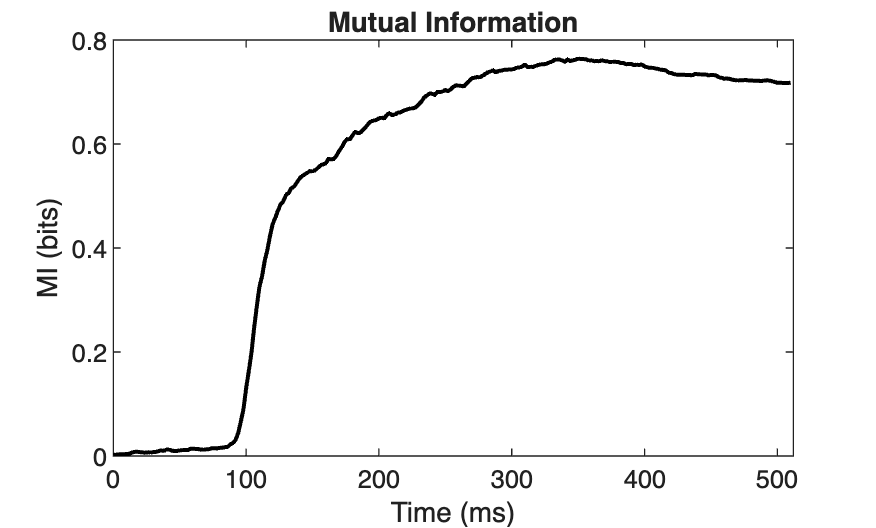

cumulative_spikes = cumsum(mtNeuron.data, 1);
num_directions = size(mtNeuron.data, 2);
num_trials = size(mtNeuron.data, 3);
num_time = size(mtNeuron.data, 1);
P_theta = 1 / num_directions;     
time_ms = (0:num_time-1) * 2;
% I(T) = I(T_n, theta) = sum_n P_T(n)log_s(P_T(n|theta)/P_T(n))

mutual_information_raw_bootstrap = zeros(num_time, 1);
for t = 1:num_time
    counts = squeeze(cumulative_spikes(t, :, :)); 
    count_vals = 0:max(counts(:));
    num_vals   = length(count_vals);

    % P(n | theta)
    Pn_given_theta = zeros(num_directions, num_vals);
    for d = 1:num_directions
        for ni = 1:num_vals
            Pn_given_theta(d, ni) = mean(counts(d, :) == count_vals(ni));
        end
    end

    % P(n), avg
    Pn = mean(Pn_given_theta, 1);
    mi_t = 0;
    for d = 1:num_directions
        Pn_d = Pn_given_theta(d, :);
        mask = Pn_d > 0 & Pn > 0;  
        mi_t = mi_t + P_theta * sum(Pn_d(mask) .* log2(Pn_d(mask) ./ Pn(mask)));
    end
    mutual_information_raw_bootstrap(t) = mi_t;
end

figure;
plot(time_ms, mutual_information_raw_bootstrap, 'k-', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('MI (bits)');
title('Mutual Information');
xlim([0 512]);

Before the neuron responds, the cumulative spike count is very close to zero. We can see this in the time before 100ms on our plot where it looks mostly flat. This means that for every trial regardless of direction, the neuron hasn't fired so therefore mutual information will be 0. The rapid increase is when the neuron starts firing. Trials of the neuron's preferred direction cause a larger increase in cumulative spike count, while trials not of the neuron's preferred direction cause the cumulative spike count to stay around 0. This means that there is a greater difference between P(n) and P(n|theta), which causes the mutual information to increase as well. 

## Problem 3

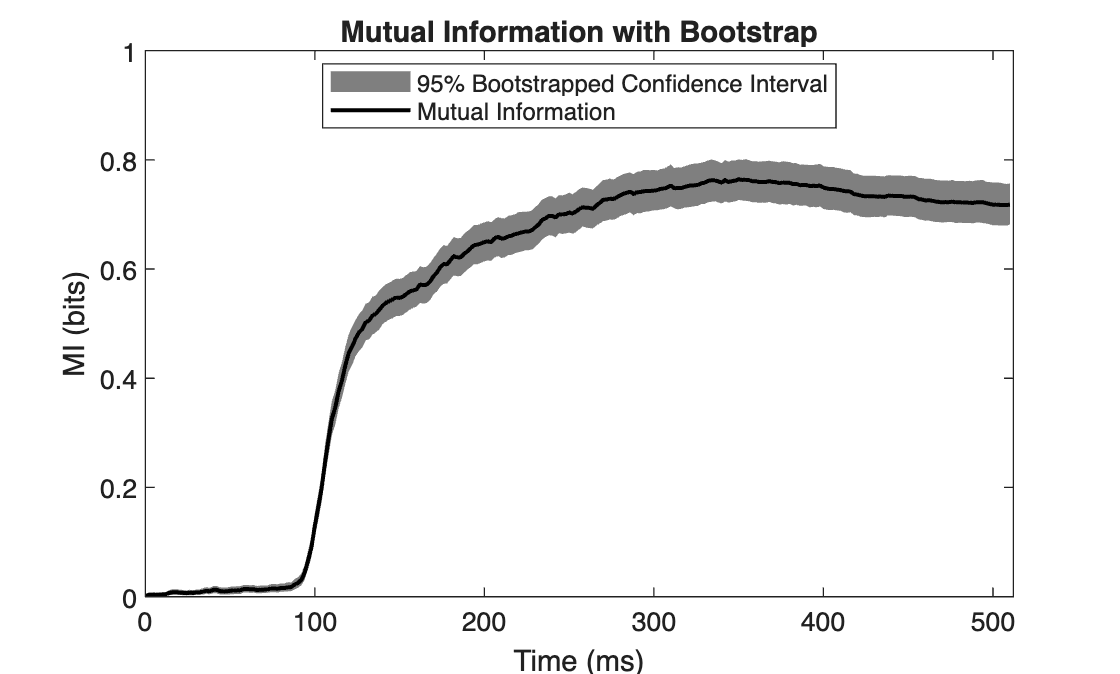

n_boot = 1000;                        
MI_boot = zeros(num_time, n_boot);

for b = 1:n_boot
    boot_spikes = zeros(num_time, num_directions, num_trials);
    for d = 1:num_directions
        idx = randi(num_trials, 1, num_trials);
        boot_spikes(:, d, :) = cumulative_spikes(:, d, idx);
    end

    MI_raw_boot = zeros(num_time, 1);
    for t = 1:num_time
        counts = squeeze(boot_spikes(t, :, :));
        count_vals = 0:max(counts(:));
        num_vals   = length(count_vals);
    
        % P(n | theta)
        Pn_given_theta = zeros(num_directions, num_vals);
        for d = 1:num_directions
            for ni = 1:num_vals
                Pn_given_theta(d, ni) = mean(counts(d, :) == count_vals(ni));
            end
        end
    
        % P(n), avg
        Pn = mean(Pn_given_theta, 1);
        mi_t = 0;
        for d = 1:num_directions
            Pn_d = Pn_given_theta(d, :);
            mask = Pn_d > 0 & Pn > 0;  
            mi_t = mi_t + P_theta * sum(Pn_d(mask) .* log2(Pn_d(mask) ./ Pn(mask)));
        end
        MI_boot(t, b) = mi_t;
    end
    
end

MI_boot_mean = mean(MI_boot, 2);
MI_boot_centered = MI_boot - MI_boot_mean + mutual_information(:);

MI_low  = prctile(MI_boot_centered, 2.5,  2);
MI_high = prctile(MI_boot_centered, 97.5, 2);

figure;
fill([time_ms, fliplr(time_ms)], ...
     [MI_low', fliplr(MI_high')], ...
     [0 0 0], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
plot(time_ms, mutual_information, 'k-', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('MI (bits)');
title('Mutual Information with Bootstrap');
xlim([0 512]);
legend('95% Bootstrapped Confidence Interval', 'Mutual Information', 'Location', 'best');

We need to resample within each direction condition and not pool all the trials together before bootstrapping. This is to preserve the P(n|theta) conditional probability.

## Problem 4 

% ── Method: baseline threshold ──────────────────────────────────────────────
% We define latency as the first time bin at which the bias-corrected MI
% exceeds the pre-stimulus mean + 2 SD of the pre-stimulus MI.
% The pre-stimulus period is t < 0, i.e. bins before stimulus onset (t=0).
% Using the data's own noise floor is principled: it adapts to this neuron's
% variability rather than relying on an arbitrary absolute threshold.
%
% The stimulus begins at t=0 (bin 1). Since recordings start at t=0 and
% the array has no negative-time baseline, we use the first ~50ms (bins 1-25)
% as a proxy pre-stimulus period — before the neuron could plausibly respond
% (given typical MT latencies of ~50-80ms). We require the threshold to be
% exceeded for at least 3 consecutive bins to avoid single-bin noise spikes.

% ── Define proxy pre-stimulus window ────────────────────────────────────────
pre_bins    = 1:30;% 0–60 ms
baseline_mu = mean(mutual_information(pre_bins));
baseline_sd = std(mutual_information(pre_bins));
threshold   = baseline_mu + 2 * baseline_sd;

% ── Find first sustained crossing ───────────────────────────────────────────
n_consec = 3;   % require 3 consecutive bins above threshold (~6 ms)
above    = mutual_information > threshold;
latency_bin = NaN;
for t = 1:(num_time - n_consec + 1)
    if all(above(t:t+n_consec-1))
        latency_bin = t;
        break;
    end
end
latency_ms = (latency_bin - 1) * 2;   % convert bin → ms
fprintf('Estimated latency: %d ms (bin %d)\n', latency_ms, latency_bin);

% ── MI fractions ─────────────────────────────────────────────────────────────
% "Within the first X ms of the neural response" means X ms after latency,
% not after stimulus onset.

total_MI = mutual_information(end);   % final (asymptotic) value

% 50 ms after latency
bin_50  = latency_bin + round(50  / 2);   % 50ms / 2ms per bin
bin_100 = latency_bin + round(100 / 2);   % 100ms / 2ms per bin
bin_50  = min(bin_50,  num_time);
bin_100 = min(bin_100, num_time);

MI_at_50  = mutual_information(bin_50);
MI_at_100 = mutual_information(bin_100);

frac_50  = MI_at_50  / total_MI;
frac_100 = MI_at_100 / total_MI;

fprintf('MI at 50ms after latency:  %.3f bits (%.1f%% of total)\n', MI_at_50,  frac_50*100);
fprintf('MI at 100ms after latency: %.3f bits (%.1f%% of total)\n', MI_at_100, frac_100*100);

% ── Plot ─────────────────────────────────────────────────────────────────────
figure;
fill([time_ms, fliplr(time_ms)], ...
     [MI_low', fliplr(MI_high')], ...
     [0 0 0], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
plot(time_ms, mutual_information, 'k-', 'LineWidth', 1.5);
yline(threshold,    'b--', 'Threshold',          'LabelVerticalAlignment','bottom');
xline(latency_ms,   'r--', sprintf('Latency: %d ms', latency_ms));
xline(time_ms(bin_50),  'g--', '+50ms');
xline(time_ms(bin_100), 'm--', '+100ms');

% Annotate fractions
text(time_ms(bin_50)+4,  MI_at_50,  sprintf('%.1f%%', frac_50*100),  'Color','g','FontSize',9);
text(time_ms(bin_100)+4, MI_at_100, sprintf('%.1f%%', frac_100*100), 'Color','m','FontSize',9);

xlabel('Time (ms)');
ylabel('MI (bits)');
title('Mutual Information with Bootstrap');
xlim([0 512]);
legend('95% Bootstrapped Confidence Interval', 'Mutual Information', 'Location', 'best');